We first import the data from the data file, and then we generate a random vector x with 10% of the entries non-zero. The vector b is generated by multiplying the matrix A and the vector x.

clear all;clc;
rand('seed', 0);
randn('seed', 0);

n = 30;
m = 10;
A = randn(m,n);

x = sprandn(n, 1, 0.1*n);
b = A*x;

xtrue = x;

We then call the function Basis_pursuit.m, which contains the ADMM algorithm. We set the parameters rho, alpha to be 1.0. We then save the output of the function as x, and the history of the algorithm as history.

[x history] = Basis_pursuit(A, b, 1.0, 1.0);

iter	    r norm	   eps pri	    s norm	  eps dual	 objective
  1	    2.1455	    0.0240	    0.3756	    0.0220	      9.49
  2	    1.2821	    0.0246	    1.5779	    0.0332	      8.62
  3	    0.7697	    0.0326	    1.2111	    0.0354	      7.98
  4	    0.8756	    0.0371	    0.5554	    0.0368	      8.45
  5	    0.7662	    0.0373	    0.3617	    0.0382	      8.73
  6	    0.3543	    0.0349	    0.5447	    0.0387	      7.41
  7	    0.2137	    0.0334	    0.4236	    0.0381	      7.25
  8	    0.3035	    0.0329	    0.1683	    0.0374	      7.71
  9	    0.2479	    0.0327	    0.0969	    0.0371	      7.45
 10	    0.1514	    0.0328	    0.1500	    0.0371	      6.97
 11	    0.1002	    0.0329	    0.1479	    0.0373	      6.63
 12	    0.0870	    0.0328	    0.1249	    0.0375	      6.56
 13	    0.0840	    0.0327	    0.1039	    0.0378	      6.57
 14	    0.0804	    0.0325	    0.0895	    0.0380	      6.57
 15	    0.0774	    0.0324	    0.0715	    0.0381	      6.60
 16	    0.0711	    0.0324	    0.0610	    0.0381	      6

.We then plot the objective function value f(x^k) + g(z^k) versus the number of iterations k.

We then plot the residual norm ||r||_2 versus the number of iterations k.

We then plot the residual norm ||s||_2 versus the number of iterations k.

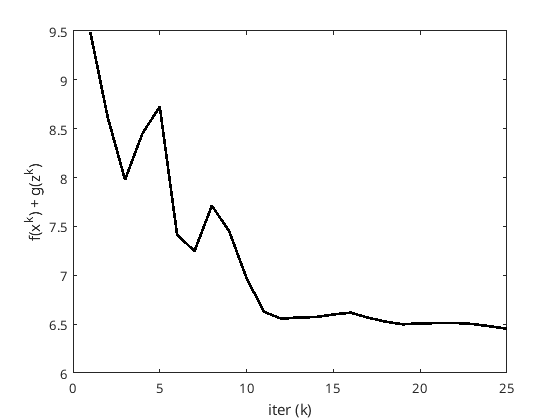

K = length(history.objval);

h = figure;
plot(1:K, history.objval, 'k', 'MarkerSize', 10, 'LineWidth', 2);
ylabel('f(x^k) + g(z^k)'); xlabel('iter (k)');

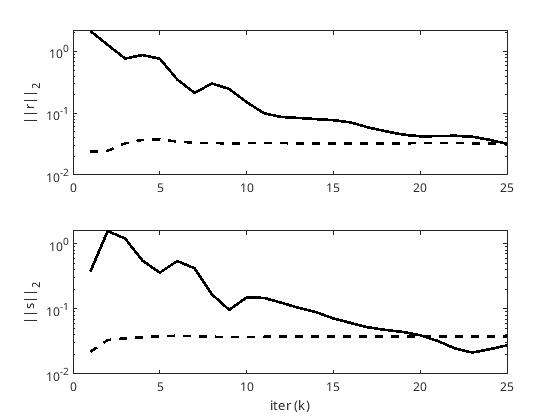


g = figure;
subplot(2,1,1);
semilogy(1:K, max(1e-8, history.r_norm), 'k', ...
    1:K, history.eps_pri, 'k--',  'LineWidth', 2);
ylabel('||r||_2');

subplot(2,1,2);
semilogy(1:K, max(1e-8, history.s_norm), 'k', ...
    1:K, history.eps_dual, 'k--', 'LineWidth', 2);
ylabel('||s||_2'); xlabel('iter (k)');